# Tutorial of rate models of working memory and decision making in the frontoparietal cortex

This tutorial shows how to implement the meanfield rate model of working memory and decision making in the frontoparietal cortex presented in Murray, Jaramillo et al. 2017.

- **Goals**: 

- llustrate the creation and usage of a local network model in DynaSim.

- Show how to combine two local modules through long-range connections in DynaSim.

- **Structure**: After a brief introduction, the first section in the tutorial show how to load `DynaSim` and set up the model. The execution of the model is done in section Run the simulation.  Visualization of the results is explained in section Visualize the results.

- **References:**

- Murray JD, Jaramillo J, Wang XJ. Working Memory and Decision-Making in a Frontoparietal Circuit Model. J Neurosci. 2017;37(50):12167-12186. doi:10.1523/JNEUROSCI.0343-17.2017

- Wong KF, Huk AC, Shadlen MN, Wang XJ. Neural circuit dynamics underlying accumulation of time-varying evidence during perceptual decision making. Front Comput Neurosci. 2007;1:6. Published 2007 Nov 2. doi:10.3389/neuro.10.006.2007

- Wong KF, Wang XJ. A recurrent network mechanism of time integration in perceptual decisions. J Neurosci. 2006;26(4):1314-1328. doi:10.1523/JNEUROSCI.3733-05.2006

## Background

The rate model of working memory and decision making in the frontoparietal cortex presented in Murray, Jaramillo et al. 2017 builds upon the meanfield approach formalized in Wong and Wang 2006 and Wong, Huk et al. 2007.

## Load DynaSim

If you haven't loaded DynaSim, do it.

dynasim_path = '../../..';
addpath(genpath(dynasim_path));

## 1. Implementation

In this section, we specify the initial settings both of the simulation (how and for how long we integrate the model) and that of the model itself (all its mechanisms and their parameters).

### Simulation parameters

Here, we specify the integration parameters: the integration time step (dt), the solver that we will be using (e.g., euler), the duration of the simulation, and an initial onset time (different than 0, if wanted). DynaSim allows compiling the code into a MEX file (compile_flag set to 1; although in general this is not required because meanfiled rate models run usually fast). DynaSim can also display detailed logs about the simulation (sim_log_flag and verbose_flag).

%% Simulation parameters

tstart = 0;        % simulation onset
duration = 5;      % simulation duration
dt = 0.1e-3;       % fixed time step, s
solver = 'euler';  % solver
compile_flag = 0;  % whether to compile simulation
sim_log_flag = 0;  % whether to display simulation progress
verbose_flag = 0;  % whether to display verbose logs
solver_options = {'time_limits',[tstart,duration],'solver',solver,'dt',dt,'compile_flag',compile_flag,'sim_log_flag',sim_log_flag,'verbose_flag',verbose_flag};


### Model specification

We start defining the ordinary differential equations (ODEs) we want to simulate. Later on, we will embed these equations into the model specification, which we define in Section Population specification. In this case we integrate each cell's NMDA synaptic gating variable (state variable sNMDA) according to the instantaneous firing rate at each time step. For this, we use a DynaSim linker (@FR) that is computed internally by the fIcurve mechanism. We also need to define the initial conditions of the state variable (sNMDA), i.e., its initial value.

%% Reduced mean-field rate model

% define equations of cell model
eqns = {
         % synaptic gating
         'dsNMDA/dt = -sNMDA/tau_sNMDA + gamma_sNMDA.*(@FR).*(1-sNMDA)'
         'sNMDA(0) = 0'
       };

### Cell multiplicity

We start with a local network model, which consists of two different populations of neurons. However, since the model is implemented as a meanfield rate model, the dynamics of each of these populations can be summarized by a single neuron representing the average dynamics of the whole population.

nNeurons = 1;
multiplicity = [nNeurons, nNeurons];

### Population specification

Here we specify the details of the two populations in the model, A and B: number of neurons, main equations, list of mechanisms embedded in each neuron's model and parameters that should be overriden from default values:

s = []; % Create an empty structure to write DynaSim's model full specification

s.populations(1).name = 'A';
s.populations(1).size = multiplicity(1);
s.populations(1).equations = eqns;
s.populations(1).mechanism_list = {'fIcurve','iBckg','iApp'};
s.populations(1).parameters = {'tau_sNMDA', 60e-3, 'gamma_sNMDA', 0.641,'app_evidence', 0.0295, 'app_onset', 1, 'app_offset', 1.5};

s.populations(2).name = 'B';
s.populations(2).size = multiplicity(2);
s.populations(2).equations = eqns;
s.populations(2).mechanism_list = {'fIcurve','iBckg','iApp'};
s.populations(2).parameters = {'tau_sNMDA', 60e-3, 'gamma_sNMDA', 0.641, 'app_evidence', 0.0295, 'app_onset', 3, 'app_offset', 3.5};

### Connections specification

Here we set the recurrent synaptic connections among the populations and specify their synaptic mechanism:

s.connections(1).direction = 'A->A';
s.connections(1).mechanism_list = {'iSynap'};
s.connections(2).direction = 'A->B';
s.connections(2).mechanism_list = {'iSynap'};
s.connections(3).direction = 'B->A';
s.connections(3).mechanism_list = {'iSynap'};
s.connections(4).direction = 'B->B';
s.connections(4).mechanism_list = {'iSynap'};

### Run the simulation

Once the model is properly specified, we proceed to run the simulation according to the simulation parameters, model specification, and connections specification. For this we use the 'vary' argument in DynaSim, so we can run more than a single simulation in one call. Specifically, we vary the strength of the recurrent connections as follows:

% connectivity strength

Js = [0.35 0.4182]; % nA
Jt = 0.28387;       % nA

Jsame = 0.5*(Jt + Js);
Jdiff = 0.5*(Jt - Js);

% run various simulations as specified

J_values(:,1,:) = [Jsame(1) Jdiff(1) Jdiff(1) Jsame(1)];
J_values(:,2,:) = [Jsame(2) Jdiff(2) Jdiff(2) Jsame(2)];

vary = {
          '(A->A,A->B,B->A,B->B)', 'J', J_values;
       };

% This is useful to double-check the intended vary combinations
% varyset = dsVary2Modifications(vary);
% varyset{:}

data = dsSimulate(s,'vary',vary,solver_options{:});

### Visualize the results

For this, we display the dynamics of the rate of the two populations A (in blue) and B (in red) as in Fig 2A and 2B of the paper:

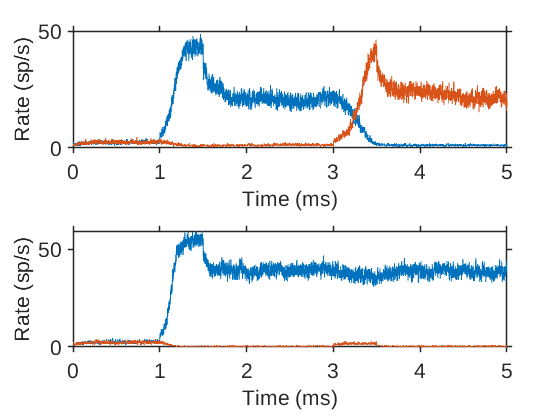

fontSize = 16;
lineWidth = 1;

figure
for iSim = 1:numel(data)
  subplot(numel(data),1,iSim)
  plot(data(iSim).time, data(iSim).A_fIcurve_FR, data(iSim).time, data(iSim).B_fIcurve_FR,'LineWidth',lineWidth)
  set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
  xlabel('Time (ms)','fontSize',fontSize)
  ylabel('Rate (sp/s)','fontSize',fontSize)
end

## 2. Two modules

Here, we show how to create DynaSim specification structure for the two modules (PPC->PFC) using dsCombineSpecification.

### Population and connection specification

We start by simply copying each module to its generic version and then we rename each population and connection accordingly. After this, we call dsCombineSpecification to obtain the specification of the two modules together:

s1 = s;
s2 = s;

s1.populations(1).name = 'PPC_A';
s1.populations(2).name = 'PPC_B';
s1.connections(1).direction = 'PPC_A->PPC_A';
s1.connections(2).direction = 'PPC_A->PPC_B';
s1.connections(3).direction = 'PPC_B->PPC_A';
s1.connections(4).direction = 'PPC_B->PPC_B';

s2.populations(1).name = 'PFC_A';
s2.populations(2).name = 'PFC_B';
s2.connections(1).direction = 'PFC_A->PFC_A';
s2.connections(2).direction = 'PFC_A->PFC_B';
s2.connections(3).direction = 'PFC_B->PFC_A';
s2.connections(4).direction = 'PFC_B->PFC_B';

s = dsCombineSpecifications(s1,s2);

### Intra-module parameters and connections

We replicate Fig. 2 E and F in the paper. For this we need to readjust population parameters and connectivity strengths as follows:

s.populations(1).parameters = {'tau_sNMDA', 60e-3, 'gamma_sNMDA', 0.641, 'app_evidence', 0.0118, 'app_onset', 0.5, 'app_offset', 2};
s.populations(2).parameters = {'tau_sNMDA', 60e-3, 'gamma_sNMDA', 0.641, 'app_evidence', 0.0118, 'app_onset', 0.5, 'app_offset', 2};

s.populations(3).parameters = {'tau_sNMDA', 60e-3, 'gamma_sNMDA', 0.641};
s.populations(4).parameters = {'tau_sNMDA', 60e-3, 'gamma_sNMDA', 0.641};

Js_PPC = Js(1);
Jsame_PPC = 0.5*(Jt + Js_PPC);
Jdiff_PPC = 0.5*(Jt - Js_PPC);

s.connections(1).parameters = {'J', Jsame_PPC};
s.connections(2).parameters = {'J', Jdiff_PPC};
s.connections(3).parameters = {'J', Jdiff_PPC};
s.connections(4).parameters = {'J', Jsame_PPC};

Js_PFC = Js(2);
Jsame_PFC = 0.5*(Jt + Js_PFC);
Jdiff_PFC = 0.5*(Jt - Js_PFC);

s.connections(5).parameters = {'J', Jsame_PFC};
s.connections(6).parameters = {'J', Jdiff_PFC};
s.connections(7).parameters = {'J', Jdiff_PFC};
s.connections(8).parameters = {'J', Jsame_PFC};

### Inter-module connections

Here, we specify the properties of the long-range connections:

Jt_long_range = 0;

Js_PPCtoPFC = 0.15; % nA
Jsame_PPCtoPFC = 0.5*(Jt_long_range + Js_PPCtoPFC);
Jdiff_PPCtoPFC = 0.5*(Jt_long_range - Js_PPCtoPFC);

s.connections(9).direction='PPC_A->PFC_A';
s.connections(9).mechanism_list='iSynap';
s.connections(9).parameters = {'J', Jsame_PPCtoPFC};
s.connections(10).direction='PPC_A->PFC_B';
s.connections(10).mechanism_list='iSynap';
s.connections(10).parameters = {'J', Jdiff_PPCtoPFC};
s.connections(11).direction='PPC_B->PFC_A';
s.connections(11).mechanism_list='iSynap';
s.connections(11).parameters = {'J', Jdiff_PPCtoPFC};
s.connections(12).direction='PPC_B->PFC_B';
s.connections(12).mechanism_list='iSynap';
s.connections(12).parameters = {'J', Jsame_PPCtoPFC};

Js_PFCtoPPC = 0.04; % nA
Jsame_PFCtoPPC = 0.5*(Jt_long_range + Js_PFCtoPPC);
Jdiff_PFCtoPPC = 0.5*(Jt_long_range - Js_PFCtoPPC);

s.connections(9).direction='PFC_A->PPC_A';
s.connections(9).mechanism_list='iSynap';
s.connections(9).parameters = {'J', Jsame_PFCtoPPC};
s.connections(10).direction='PFC_A->PPC_B';
s.connections(10).mechanism_list='iSynap';
s.connections(10).parameters = {'J', Jdiff_PFCtoPPC};
s.connections(11).direction='PFC_B->PPC_A';
s.connections(11).mechanism_list='iSynap';
s.connections(11).parameters = {'J', Jdiff_PFCtoPPC};
s.connections(12).direction='PFC_B->PPC_B';
s.connections(12).mechanism_list='iSynap';
s.connections(12).parameters = {'J', Jsame_PFCtoPPC};

### Run the simulations and visualize the results

Finally, we are in the position to specify the new simulation parameters, run the simulations and visualize the results.

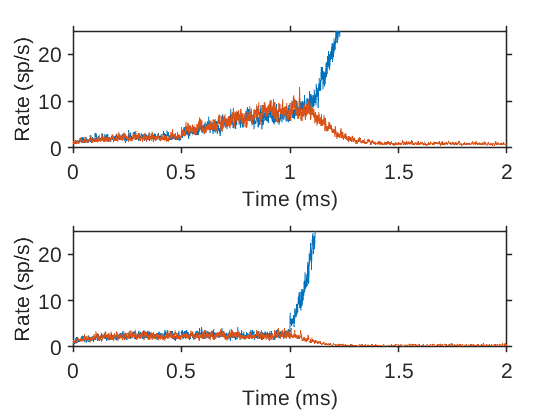

% simulation parameters readjustment
duration = 2;      % new simulation duration
solver_options = {'time_limits',[tstart,duration],'solver',solver,'dt',dt,'compile_flag',compile_flag,'sim_log_flag',sim_log_flag,'verbose_flag',verbose_flag};

% nsims simulations with different random seed
nsims = 1; % 100

figure
for iSim = 1:nsims
  data_2modules(iSim) = dsSimulate(s,solver_options{:});

  subplot(211)
  hold on
  plot(data_2modules(iSim).time, data_2modules(iSim).PPC_A_fIcurve_FR, data_2modules(iSim).time, data_2modules(iSim).PPC_B_fIcurve_FR,'LineWidth',lineWidth)
  ylim([0 25])
  set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
  xlabel('Time (ms)','fontSize',fontSize)
  ylabel('Rate (sp/s)','fontSize',fontSize)

  subplot(212)
  hold on
  plot(data_2modules(iSim).time, data_2modules(iSim).PFC_A_fIcurve_FR, data_2modules(iSim).time, data_2modules(iSim).PFC_B_fIcurve_FR,'LineWidth',lineWidth)
  ylim([0 25])
  set(gca,'fontSize',fontSize,'LineWidth',lineWidth,'TickDir','out','Box','on')
  xlabel('Time (ms)','fontSize',fontSize)
  ylabel('Rate (sp/s)','fontSize',fontSize)

  drawnow
end